clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = 273.15+20;
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


n = param.n;
% A = [ 0 1 ; 1 0 ];
% B = [1 ; 0];
% C = [1 15];
% Q = eye(2);

yalmip('clear')
gamma = sdpvar(1);
A = [param.model.A+0*eye(12), param.model.B, zeros(12,4);
     zeros(4,12), -gamma/2*eye(4), zeros(4,4);
     zeros(4,12), zeros(4,4), -gamma/2*eye(4)];
B = [param.model.B; zeros(4,4); eye(4)];
C = [blkdiag([zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)]), zeros(8,4), zeros(8,4)];
Q = eye(20);
tol = 1e-2;
tol_alpha = 0;

% Step 1
p = cell(1,param.n);
for i=1:param.n
    p{i} = sdpvar(3);
end
P = blkdiag((blkdiag(p{:})),eye(4),eye(4));

constraints = [A.' * P + P * A + Q,P * B;
                B.' * P, eye(n)] >= 0;
constraints = [constraints, P >= 0];
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, -trace(P), options);
X(:,:,1) = value(P);
i = 1;

while 1
    % Step 2
    f = cell(1,param.n);
    for j=1:param.n
        f{j} = sdpvar(1,2,'full');
    end
    F = blkdiag(f{:});

    alpha = sdpvar(1);
    constraints = [A.'*P + P*A - X(:,:,i)*(B*B.')*P - P*(B*B.')*X(:,:,i) + X(:,:,i)*(B*B.')*X(:,:,i) - alpha*P , (B.'*P + F*C).';
                    (B.'*P + F*C), -eye(n)] <= 0;
    constraints = [constraints, P >= 0];
    options = sdpsettings('verbose',0,'solver','mosek');
    sol = bisection(constraints, alpha, options);
    alpha_min = value(alpha);
    % Step 3
    if(alpha_min <= tol_alpha)
        break
    end
    % Step 4
    constraints = [A.'*P + P*A - X(:,:,i)*(B*B.')*P - P*(B*B.')*X(:,:,i) + X(:,:,i)*(B*B.')*X(:,:,i) - alpha_min*P , (B.'*P + F*C).';
                    (B.'*P + F*C), -eye(n)] <= 0;
    constraints = [constraints, P >= 0];
    options = sdpsettings('verbose',0,'solver','mosek');
    sol = optimize(constraints, trace(P), options);
    P_min(:,:,i) = value(P);
    
    % Step 5
    if (norm(X(:,:,i) - P_min(:,:,i)) < tol)
        % Step 6
        break
    else
        i = i + 1;
        X(:,:,i) = P_min(:,:,i-1);
    end
end

Ks = zeros(1,3,param.n);
for j=1:param.n
    Ks(1,2:3,j) = F(j,2*(j-1)+1:2*j);
end
param.ctrl.Ks = Ks;
param.ctrl.Ks

ans = ans(:,:,1) =

         0    5.3416    0.8644


ans(:,:,2) =

         0    5.8931    0.9901


ans(:,:,3) =

         0    5.8364    0.9977


ans(:,:,4) =

         0    6.1951    1.0447


0.000000, 0.000000, -0.102904, 0.000000, 


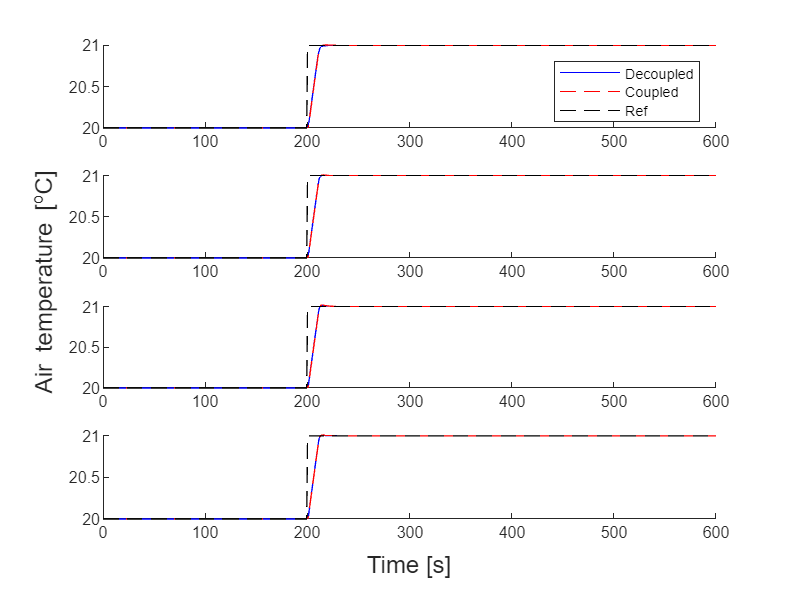


K = blkdiag(param.ctrl.Ks(1,2:3,1),param.ctrl.Ks(1,2:3,2),param.ctrl.Ks(1,2:3,3),param.ctrl.Ks(1,2:3,4));

[decoupledResults,coupledResults] = util.SimulateStep(param,"Output_Feedback",0);

s = tf('s');
Cy = blkdiag([zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)],[zeros(2,1), eye(2)]);
M = K * Cy/(s * eye(12) - (param.model.A + param.model.B * K * Cy) )*param.model.B;
hinfnorm(M)

ans = 1.1110



listOfUncertainties = {[-.9,1]};
m = length(listOfUncertainties);
Uncertainties = zeros(m,m,m^2);
if(m == 1)% check if the inputs share uncertainties or if they have individual uncertainties
    comb = combinations(cell2mat(listOfUncertainties(1)));
else
    comb = combinations(cell2mat(listOfUncertainties(1)),cell2mat(listOfUncertainties(2)),cell2mat(listOfUncertainties(3)),cell2mat(listOfUncertainties(4)));
end
combDouble = table2array(comb);
for i=1:length(combDouble)
    Uncertainties(:,:,i) = diag(combDouble(i,:));
end
yalmip('clear')
p = cell(1,param.n);
for i=1:param.n
    p{i} = sdpvar(3);
end
P = blkdiag(p{:});
sigma = sdpvar(1);
constraints = [param.model.A.'*P + P*param.model.A - sigma*(Cy.'*Cy) <= 0];
for i=1:length(Uncertainties)
    constraints = [constraints, (param.model.A + param.model.B*(eye(m) + Uncertainties(i))*K*Cy).'*P + P*(param.model.A + param.model.B*(eye(m) + Uncertainties(i))*K*Cy)<=0];
end
constraints = [constraints, P>=eye(12), sigma >= 0];
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, [], options)

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0426
       solvertime: 0.0044
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


P_min = value(P)

P_min =   122.8594  -38.5458   13.8650         0         0         0         0         0         0         0         0         0
  -38.5458   51.7642    3.7160         0         0         0         0         0         0         0         0         0
   13.8650    3.7160    6.1320         0         0         0         0         0         0         0         0         0
         0         0         0   75.3556  -32.8761    8.6312         0         0         0         0         0         0
         0         0         0  -32.8761   44.6640    2.0599         0         0         0         0         0         0
         0         0         0    8.6312    2.0599    4.0668         0         0         0         0         0         0
         0         0         0         0         0         0   59.2043  -29.4019    6.6422         0         0         0
         0         0         0         0         0         0  -29.4019   40.0362    1.4097         0         0         0
         0         0    

eig(P_min)

ans =     1.4314
    1.6063
    1.8099
    2.7149
   20.1622
   24.0019
   25.5713
   37.3551
   80.8125
   92.4813
